# Norm based robust control

### Design of $H_{\infty }$ and $H_2$ robust controllers


$$x\left(t\right)=\left\lbrack \begin{array}{c}
i_{L_m } \left(t\right)\\
v_c \left(t\right)
\end{array}\right\rbrack \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;u\left(t\right)=\left\lbrack \begin{array}{c}
v_s \left(t\right)\\
V_d 
\end{array}\right\rbrack \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;y\left(t\right)=\left\lbrack v\left(t\right)\right\rbrack$$



$$\begin{array}{l}
\dot{x} =A\;x+B\;u\\
y=C\;x+D\;u
\end{array}$$


clc 
clear all
close all 
DuCy=20; 
Io=5; Vo=5;
Vg=24; Vd=0;

Vs=[Vg Vd];
X=[Io Vo];

[A,B,C,D,G] =flyback_ss(Vs,X,DuCy)

A = 	1.0e+07 *

   -0.0400   -7.6000
    0.0380   -0.0000


B =    -40000000    76000000
           0           0


C =      0     1


D =      0     0


G =
 
                                        
  1e05 s^3 - 2.58e13 s^2 - 7.447e18 s   
                                        
                              - 7.462e26
                                        
  --------------------------------------
                                        
  s^4 + 8e05 s^3 + 5.792e13 s^2         
                                        
                  + 2.31e19 s + 8.341e26
                                        
 
Continuous-time transfer function.




% Create the state-space model
sys = ss(A, B, C, D);
sys.StateName = {'i_L';'V_c'}

sys =
 
  A = 
             i_L       V_c
   i_L    -4e+05  -7.6e+07
   V_c   3.8e+05    -0.001
 
  B = 
             u1       u2
   i_L   -4e+07  7.6e+07
   V_c        0        0
 
  C = 
       i_L  V_c
   y1    0    1
 
  D = 
       u1  u2
   y1   0   0
 
Continuous-time state-space model.



sys.InputName = {'vs';'Vd'};
sys.OutputName = {'v'};

G=ss(A,B,C,D);
s=tf('s');
W1=100/(s+1);   W2=1e-5;    W3=s/1000;
nmeas = 1;
ncont = 2;

Gc1 = zpk(h2syn(G,nmeas,ncont))

Gc1 =
 
  From input to output...
             72.427 (s+2362)
   1:  ----------------------------
       (s^2 + 2.235e06s + 2.946e13)
 
             -137.61 (s+2362)
   2:  ----------------------------
       (s^2 + 2.235e06s + 2.946e13)
 
Continuous-time zero/pole/gain model.




[Gc2,CL,g] = hinfsyn(G,nmeas,ncont)

Gc2 =
 
  A = 
               x1          x2
   x1  -2.235e+06  -7.754e+07
   x2     3.8e+05      -30.15
 
  B = 
          u1
   x1   7253
   x2  30.15
 
  C = 
             x1        x2
   y1  0.009952  0.008302
   y2  -0.01891  -0.01577
 
  D = 
       u1
   y1   0
   y2   0
 
Continuous-time state-space model.


CL =
 
  A = 
               x1          x2
   x1      -4e+05    -7.6e+07
   x2     3.8e+05      -0.001
   x3           0        7253
   x4           0       30.15
 
               x3          x4
   x1  -1.835e+06  -1.531e+06
   x2           0           0
   x3  -2.235e+06  -7.754e+07
   x4     3.8e+05      -30.15
 
  B = 
     Empty matrix: 4-by-0
 
  C = 
     Empty matrix: 0-by-4
 
  D = 
     []
 
Continuous-time state-space model.



g = 0

**Modeling Plant Variability as Uncertainty**

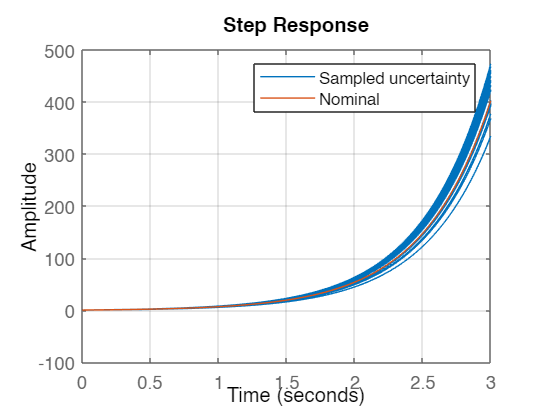

Pnom = tf(2,[1 -2]);

p1 = Pnom*tf(1,[.06 1]);              % extra lag
p2 = Pnom*tf([-.02 1],[.02 1]);       % time delay
p3 = Pnom*tf(50^2,[1 2*.1*50 50^2]);  % high frequency resonance
p4 = tf(2.4,[1 -2.2]);                % pole/gain migration
Parray = stack(1,p1,p2,p3,p4);
orderWt = 4;
Parrayg = frd(Parray,logspace(-1,3,60));
[P,Info] = ucover(Parrayg,Pnom,orderWt,'InputMult');
step(P,getNominal(P),3)
grid on
legend('Sampled uncertainty','Nominal')



G=ss(P.A,P.B,P.C,P.D);
s=tf('s');
W1=100/(s+1);   W2=1e-5;    W3=s/1000;
nmeas = 1;
ncont = 5;

Gaug = augtf(G,W1,W2,W3)

Gaug =
 
  A = 
           x1      x2      x3
   x1       2   -8.88  -10.41
   x2       0   -1354   -1331
   x3       0    2728    2652
   x4       0   -2728   -2642
   x5       0    1364    1321
   x6      -1       0       0
 
           x4      x5      x6
   x1  -8.079  -3.826       0
   x2  -875.5  -309.2       0
   x3    1751   618.5       0
   x4   -1761  -618.5       0
   x5   885.5   299.2       0
   x6       0       0      -1
 
  B = 
       u1  u2
   x1   0   2
   x2   0   0
   x3   0   0
   x4   0   0
   x5   0   0
   x6   1   0
 
  C = 
              x1         x2
   y1          0          0
   y2          0          0
   y3      0.002   -0.00888
   y4         -1          0
 
              x3         x4
   y1          0          0
   y2          0          0
   y3   -0.01041  -0.008079
   y4          0          0
 
              x5         x6
   y1          0        100
   y2          0          0
   y3  -0.003826          0
   y4          0          0
 
  D = 
          u1 

Gc1 = zpk(h2syn(G,nmeas,ncont))

Error using DynamicSystem/h2syn (line 72)
There must be fewer controls than plant inputs.


[Gc2,CL,g] = hinfsyn(G,nmeas,ncont)